clc;clear; 

% Enter model parameters
    price = 1:20;                  % price of ore
    sbar  = 100;                   % initial ore stock
    delta = 0.9;                   % discount factor    

% Construct state and action spaces
    S = (0:sbar)';                 % vector of states
    X = (0:sbar)';                 % vector of actions
    n = length(S);                 % number of states
    m = length(X);                 % number of actions  

% Empty matrices to store values
    vs    = zeros(sbar+1, numel(price));
    xs     = zeros(sbar+1, numel(price));
    pstars = zeros(sbar+1, sbar+1, numel(price));

% Vectorized version
    for k=1:numel(price)
    p = price(k);
    [SS,XX] = gridmake(S,X);
    f = (p-XX./(1+SS)).*XX;
    f(XX>SS) = -inf;
    f = reshape(f,n,m);
    g = getindex(SS-XX,SS);
    g = reshape(g,n,m);
    clear SS XX
    
% Pack model data
    clear model
    model.reward     = f;
    model.transfunc  = g;
    model.discount   = delta;
    model.horizon    = inf;

% Solve model using policy iteration for each price
    [v,x,pstar] = ddpsolve(model);
    vs(:,k)=v;
    xs(:,k)=x;
    pstars(:,:,k)=pstar;
    end

Solve Bellman equation via Newton method
    1    2.7e+02
    2    6.6e+01
    3    5.0e+00
    4    1.8e+00
    5    4.4e-01
    6    1.7e-01
    7    7.9e-02
    8    2.4e-02
    9    0.0e+00
Solve Bellman equation via Newton method
    1    5.9e+02
    2    2.0e+02
    3    2.9e+01
    4    1.5e+00
    5    3.4e-01
    6    1.1e-01
    7    4.5e-02
    8    1.3e-02
    9    0.0e+00
Solve Bellman equation via Newton method
    1    1.2e+03
    2    1.5e+02
    3    1.4e+01
    4    8.4e-01
    5    2.8e-01
    6    1.1e-01
    7    4.2e-02
    8    0.0e+00
Solve Bellman equation via Newton method
    1    1.8e+03
    2    1.1e+02
    3    6.5e+00
    4    5.3e-01
    5    1.0e-01
    6    2.8e-02
    7    0.0e+00
Solve Bellman equation via Newton method
    1    2.3e+03
    2    7.6e+01
    3    3.0e+00
    4    5.3e-01
    5    8.5e-02
    6    0.0e+00
Solve Bellman equation via Newton method
    1    2.9e+03
    2    5.2e+01
    3    1.3e+00
    4    2.0e-01
    5    5.2e-03
    6 

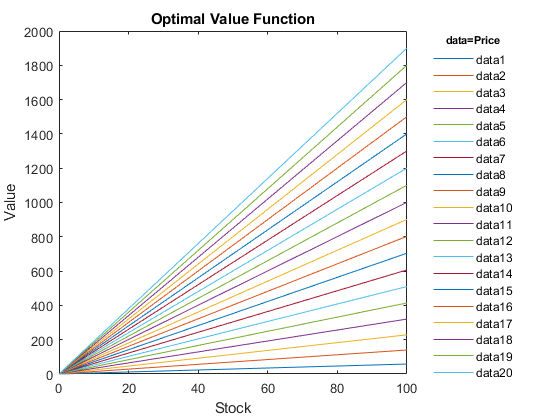

%%%%% Plots %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
  
% Plot optimal value function
    plot(S,vs);
    title('Optimal Value Function');
    xlabel('Stock'); ylabel('Value');
    lgd1 = legend('Location',"eastoutside");
    legend("Box","off");
    title(lgd1,'data=Price','FontSize',8);

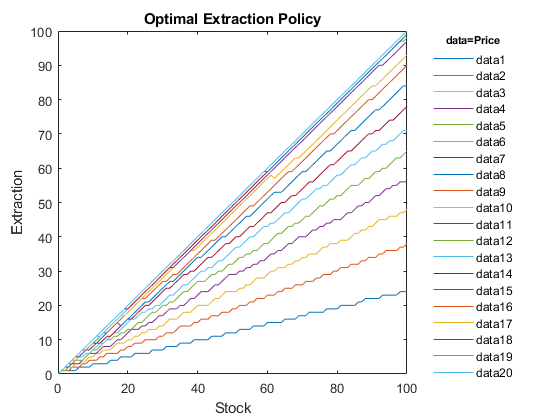

% Plot optimal policy function  
    plot(S,X(xs));
    title('Optimal Extraction Policy');
    xlabel('Stock'); ylabel('Extraction');
    lgd2=legend('Location',"eastoutside");
    legend("Box","off");
    title(lgd2,'data=Price','FontSize',8);

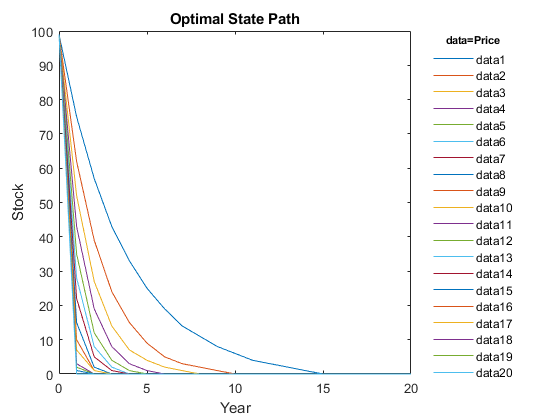

% Generate optimal path
    sinit = max(S); nyrs = 20;
    spaths = zeros(nyrs+1, numel(price));
    for z=1:numel(price)
    spath = ddpsimul(pstars(:,:,z),sinit,nyrs);
    spaths(:,z) = S(spath);
    end
% Plot optimal path
    plot(0:nyrs,spaths);
    title('Optimal State Path');
    xlabel('Year'); ylabel('Stock');
    lgd3=legend('Location',"eastoutside");
    legend("Box","off");
    title(lgd3,'data=Price','FontSize',8);